clc
close all

sig = @(t) (1e-3)*exp(t);
mprior = [2.5 0.5]';
CM = [6.7 0; 0 0.07];
tmean = [2.5411;0.2595];

Y = @(t,m) (m(1).*exp(m(2).*t));
t = [1 2 4 5 8]';
y = [3.2939 4.2699 7.1749 9.3008 20.259]';

J = @(t,m) [(exp(m(2)*t)), (m(1)*t.*exp(m(2)*t))]; %exact jacobian

max_iter = 1e6;
tol = 1e-7;

warning('off','all')

%generate roughening matrices
n =2;
L0 = eye(n);

### N0.1 a)

% convariance matrix
CD = (1e-6)*[0.7 0 0 0 0; 0 0.08 0 0 0;0 0 0.3 0 0; 0 0 0 0.1 0;0 0 0 0 0.2];
func = @(CD,CM,mprior,m) [(CD^(-0.5))*Y(t,m);(CM^(-0.5))*m] - [(CD^(-0.5))*y;(CM^(-0.5))*mprior];
jac = @(CD,CM,m) [(CD^(-0.5))*J(t,m); CM^(-0.5)]; 

[MAP, iter] = lm(CD,CM,func, jac, mprior, tol, max_iter);
disp(['Resulting MAP estimates = [',num2str(MAP'),']']);

Resulting MAP estimates = [2.5411      0.2595]


disp(['Resulting number of iterations = ',num2str(iter)]);

Resulting number of iterations = 7


### b)

[m,n] = size(J(t,mprior));
Im = eye(m);
CD = (sig(t).^2).*Im;

[MAP, iter] = lm(CD,CM,func, jac, mprior, tol, max_iter);
disp(['Resulting MAP estimates = [',num2str(MAP'),']']);

Resulting MAP estimates = [2.541     0.25952]


disp(['Resulting number of iterations = ',num2str(iter)]);

Resulting number of iterations = 5


### N0.2

mprior = tmean -  0.25*tmean;
stdm =  0.25*tmean;
CM = diag(stdm.^2)

CM =     0.4036         0
         0    0.0042


%noise in the data
stdd = Y(t,tmean) - y;

CD = diag(stdd.^2)

CD = 	1.0e+-8 *

    0.6665         0         0         0         0
         0    0.0806         0         0         0
         0         0    0.3490         0         0
         0         0         0    0.0976         0
         0         0         0         0    0.1778


[MAP, iter] = lm(CD,CM,func, jac, mprior, tol, max_iter);

MAP =     2.5411
    0.2595


iter =      6


disp(['Resulting MAP estimates = [',num2str(MAP'),']']);

Resulting MAP estimates = [2.5411      0.2595]


disp(['Resulting number of iterations = ',num2str(iter)]);

Resulting number of iterations = 6


% Covariance matrix
C = inv(J(t,MAP)'*(inv(CD))*J(t,MAP) + inv(CM));
covariance_matrix = C

covariance_matrix = 	1.0e+-9 *

    0.2389   -0.0130
   -0.0130    0.0008


Because $(\sigma_{LM})_{1} (\sigma_{LM})_{2} \ne 0$, then the computed confidence interval doesn't capture the relationship between $MAP_{1}$ and $MAP_{2}$

% %confidence interval
za = 1.96; % 95% confidence interval

% first parameter
s1 = sqrt(C(1,1)); % standard deviation

% confidence intervals 
format long
c1 = MAP(1) - za*s1;
c2 = MAP(1) + za*s1;

cf = [c1 c2];
disp(['Resulting cofidence_interval for the first estimate =  [',num2str(cf,16),']']);

Resulting cofidence_interval for the first estimate =  [2.541054921983898       2.54111550902723]



% Second parameter
s2 = sqrt(C(2,2)); % standard deviation

% confidence intervals 
c11 = MAP(2) - za*s2;
c22 = MAP(2) + za*s2;

cs = [c11 c22];
disp(['Resulting cofidence_interval for the first estimate =  [',num2str(cs,16),']']);

Resulting cofidence_interval for the first estimate =  [0.2594993499022446     0.2595027800518799]


The estimates lie with in the confidence interval.


%Correlation matrix
rho1 = C(1,1)/sqrt(C(1,1)*C(1,1));
rho12 = C(1,2)/sqrt(C(1,1)*C(2,2));
Correlation_matrix = [rho1 rho12;rho12 rho1]

Correlation_matrix =     1.0000   -0.9616
   -0.9616    1.0000


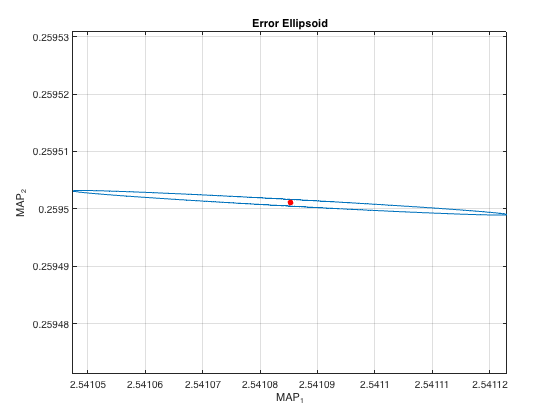

%Linearised ellipsoid
Delta = chi2inv(0.95,2); %Delta2

figure(1)
plot_ellipse(Delta,C,MAP); hold on 
plot(MAP(1),MAP(2),'.r',MarkerSize=17)
grid on
title('Error Ellipsoid')
xlabel('MAP_1'); ylabel('MAP_2')

The values of the estimates lie at the center of the ellipsoid, which implies that the estimates lie with in the confidence region.

function plot_ellipse(DELTA2,C,m)
n=5000;

%construct a vector of n equally-spaced angles from (0,2*pi)
theta=linspace(0,2*pi,n)';

%corresponding unit vector
xhat=[cos(theta),sin(theta)];
Cinv=inv(C);

%preallocate output array
r=zeros(n,2);
for i=1:n
%store each (x,y) pair on the confidence ellipse in the corresponding row of r
r(i,:)=sqrt(DELTA2/(xhat(i,:)*Cinv*xhat(i,:)'))*xhat(i,:);
end

% Plot the ellipse and set the axes.
plot(m(1)+r(:,1), m(2)+r(:,2));
axis equal
end